Right, so, firstly, using Poiseuille's law, $Q=\frac{\Delta p\pi D^4 }{128\mu \;L}$.

Secondly, ideal gas equation $\textrm{PV}=\textrm{mRT}$. Similarly, $P=\rho \text{ }\mathrm{RT}\to \rho =\frac{P}{\mathrm{RT}}=\frac{V}{m}$.

The volume of the cylinder changes as a function of time. Being a single-inlet system, the mass is also a function of time and the system is transient.

So, let $V\left(t\right)$ and $m\left(t\right)$be a function of time and the process be isothermal, then pressure inside the cylinder is given by ideal gas equation $P\left(t\right)=m\left(t\right)\frac{\textrm{RT}}{V\left(t\right)}$.

Identifying the system as a single inlet no outlet system, we obtain $Q=\frac{\text{dm}}{\text{dt}}$.

So, $\frac{\text{dm}}{\text{dt}}=\frac{\pi D^4 }{128\mu \text{ }L}\cdot \left(P_{\text{atm}} -\frac{m\left(t\right)}{V\left(t\right)}\text{RT}\right)$.

Here, $V\left(t\right)$is defined function of time.

Assume atmospheric conditions.

atm=101325;
R=8314/28;
T=298;
D=0.01;
mu=1.81e-5;
L=0.1;

Load up the symbolic lab.

syms t
V= piecewise(t<1,0.1+0.9*t, t>=1,1);
%Dm = diff(m);

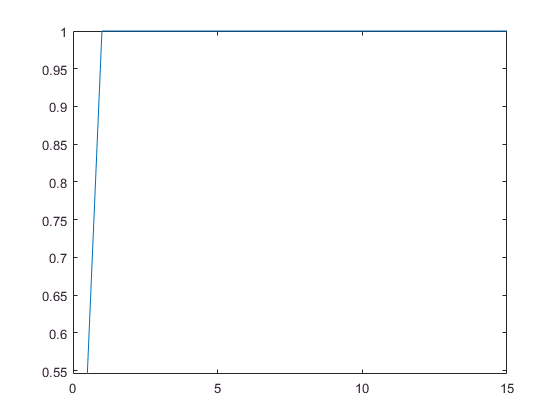

figure(1)
clf
fplot(V,[0,15])

Setup the equation.

%eqn1 = Dm1-pi*D.^4/128/mu/L * (atm - m1*R*T/V1) == 0
%eqn2 = Dm2-pi*D.^4/128/mu/L * (atm - m2*R*T/V2) == 0

Boundary conditions.

%cond1 = m(0) == atm*V1(0)/R/T
%cond2 = m2(1) == m1(1)

Hit it: solve the equation.

%[solm1, solm2] = dsolve([eqn1,eqn2],[cond1, cond2])
[tt,y]=ode45(@(tt,y) pi*D.^4/128/mu/L * (atm - y*R*T/V),[0 15], [atm*0.1/R/T])

Error using odearguments (line 113)
Inputs must be floats, namely single or double.

Error in ode45 (line 115)
    odearguments(FcnHandlesUsed, solver_name, ode, tspan, y0, options, varargin);

The plotting section.

figure(2)
clf
fplot(solm1,[0,1])